## **2.1 Анализ матриц**

**Система**

m = 1;
M = 10;
g = 9.8;
l = 0.5;

A =[0, 1, 0, 0;
   0, 0, m*g/M, 0;
   0, 0, 0, 1;
   0, 0, (M+m)*g/(M*l), 0];
B =[0;1/M;0;1/(M*l)];
C =[1,0,0,0;
    0, 0, 1, 0];
D =[0; 1/(l*M); 0; (M+m)/(m*M*l^2)];

Собственные числа и собственные векторы матрицы А

eig(A);
[V, Y] = eig(A);

Анализ системы на управляемость

U = ctrb(A, B);
rank(U);

Анализ системы на наблюдаемость

V = obsv(A, C);
rank(V);

## **2.2 Передаточные функции**

syms s
W_uy = simplify(C*inv(s*eye(4) - A)*B)
W_fy = simplify(C*inv(s*eye(4) - A)*D)

Полюса передаточных

numerator = [5, 0, -98];
denominator = [2*25,0, -2*539, 0, 0];
sys1 = tf(numerator,denominator)
pole(sys1)
zero(sys1)

numerator = 5;
denominator = [25,0,-539];
sys2 = tf(numerator,denominator)
pole(sys2)
zero(sys2)

numerator = 5;
denominator = [25,0,-539];
sys3 = tf(numerator,denominator)
pole(sys3)
zero(sys3)

numerator = 110;
denominator = [25,0,-539];
sys4 = tf(numerator,denominator)
pole(sys4)
zero(sys4)

## **2.3 Линейное моделирование**

% Создание линейной системы
sys = ss(A, [B D], C, []);

% Начальное состояние
x0 = [0.01; 0.02; 0.03; 0.04]; % Начальное состояние

% Моделирование свободного движения системы
[y, t, x] = initial(sys, x0, [0:0.01:1]);

% Визуализация результатов
figure;
plot(t, x, LineWidth=2.0);
title('$x_i(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;

legend("Position", [0.15322,0.64804,0.10357,0.25119])



## **2.4 Нелинейное моделирование**

% Время моделирования
t_start = 0;
t_end = 15;
t_step = 0.01;
t = t_start:t_step:t_end;

% Начальные условия
x0 = [0.01; 0.02; 0.03; 0.04];

% Моделирование с помощью ode45
[t, states] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g), t, x0);
% Извлечение состояний системы
theta = states(:, 3);  % Угол отклонения маятника, рад
theta_dot = states(:, 4);  % Угловая скорость маятника, рад/с
x_pos = states(:, 1);  % Позиция тележки, м
x_dot = states(:, 2);  % Скорость тележки, м/с

% Визуализация
% График перемещения тележки
plot(t, x_pos, LineWidth=2.0);
% hold on;
% plot(t, x(:,1), LineWidth=2.0, LineStyle="--");
% legend('not linear', 'linear', 'Interpreter', 'latex', 'FontSize', 16);
title('${a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Distance, $m$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График скорости тележки
plot(t, x_dot, LineWidth=2.0);
% hold on;
% plot(t, x(:,2), LineWidth=2.0, LineStyle="--");
% legend('not linear', 'linear', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Speed, $m/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угла отклонения маятника
plot(t, theta, LineWidth=2.0);
% hold on;
% plot(t, x(:,3), LineWidth=2.0, LineStyle="--");
% legend('not linear', 'linear', 'Interpreter', 'latex', 'FontSize', 16);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угловой скорости маятника
plot(t, theta_dot, LineWidth=2.0);
% hold on;
% plot(t, x(:,4), LineWidth=2.0, LineStyle="--");
% legend('not linear', 'linear', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{\varphi}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 3.1 Синтез регулятора по состоянию

Расчет регулятора

G1=[-1, 0, 0 ,0;
    0, -1.1, 0, 0;
    0, 0, -0.9, 0;
    0, 0, 0, -0.8]; % желаемый спектр
Y = [1, 1, 1, 1];
cvx_begin sdp
variable P(4,4)
A*P-P*G1 == B*Y;
cvx_end
K = -Y*pinv(P);

Моделирование системы

t_start = 0;
t_end = 15;
t_step = 0.001;
t = t_start:t_step:t_end;

% Начальные условия
x0 = [0.1; 0.2; 0.3; 0.4];
x01 = [40; 8; 0.3; 0.4];
% ограничения на систему [42.218, 8.307, 0.705, 3.054]
% Моделирование с помощью ode45
[t, x] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K*x), t, x0);

plot(t, x, LineWidth=2.0);
title('$x_1(0)=[0.1; 0.2; 0.3; 0.4]$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;

[t, x1] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K*x), t, x01);

plot(t, x1, LineWidth=2.0);
title('$x_2(0)=[40; 8; 0.3; 0.4]$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;


## 3.2 Исследование регулятора по состоянию

Зададимся четырьмя различными желаемыми спектрами матриц A+BK

Y = [1, 1, 1, 1];

GK=[-1, 1, 0 ,0;
    0, -1, 1, 0;
    0, 0, -1, 1;
    0, 0, 0, -1]; % желаемый спектр регулятора
cvx_begin sdp
variable P(4,4)
A*P-P*GK == B*Y;
cvx_end
K = -Y*pinv(P)

G1=[-2, 1, 0 ,0;
    0, -2, 1, 0;
    0, 0, -2, 1;
    0, 0, 0, -2]; % желаемый спектр
cvx_begin sdp
variable P(4,4)
A*P-P*G1 == B*Y;
cvx_end
K1 = -Y*pinv(P)

G2=[-1, 1, 0 ,0;
    0, -1, 0, 0;
    0, 0, -1.3, 0.25;
    0, 0, -0.25, -1.3]; % желаемый спектр
cvx_begin sdp
variable P(4,4)
A*P-P*G2 == B*Y;
cvx_end
K2 = -Y*pinv(P)

G3=[-2, 1, 0 ,0;
    0, -2, 0, 0;
    0, 0, -2, 0.25;
    0, 0, -0.25, -2]; % желаемый спектр
cvx_begin sdp
variable P(4,4)
A*P-P*G3 == B*Y;
cvx_end
K3 = -Y*pinv(P)

G4=[-2, 1, 0 ,0;
    0, -2, 0, 0;
    0, 0, -2, 0.5;
    0, 0, -0.5, -2]; % желаемый спектр
cvx_begin sdp
variable P(4,4)
A*P-P*G4 == B*Y;
cvx_end
K4 = -Y*pinv(P)

Моделирование системы

t_start = 0;
t_end = 2;
t_step = 0.001;
t = t_start:t_step:t_end;

% Начальные условия
x0 = [0.1; 0.2; 0.3; 4];
% ограничения на систему [42.218, 8.307, 0.705, 3.054]
% Моделирование с помощью ode45
[t, states1] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K1*x), t, x0);
[t, states2] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K2*x), t, x0);
[t, states3] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K3*x), t, x0);
[t, states4] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K4*x), t, x0);

max(abs(states1(:,1)))
max(abs(states2(:,1)))
max(abs(states3(:,1)))
max(abs(states4(:,1)))

max(abs(states1(:,3)))
max(abs(states2(:,3)))
max(abs(states3(:,3)))
max(abs(states4(:,3)))

% График перемещения тележки
plot(t, states1(:, 1), LineWidth=2.0);
hold on;
plot(t, states2(:, 1), LineWidth=2.0);
hold on;
plot(t, states3(:, 1), LineWidth=2.0);
hold on;
plot(t, states4(:, 1), LineWidth=2.0);
legend('$a_1$', '$a_2$','$a_3$', '$a_4$', 'Interpreter', 'latex', 'FontSize', 16);
title('${a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Distance, $m$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График скорости тележки
plot(t, states1(:, 2), LineWidth=2.0);
hold on;
plot(t, states2(:, 2), LineWidth=2.0);
hold on;
plot(t, states3(:, 2), LineWidth=2.0);
hold on;
plot(t, states4(:, 2), LineWidth=2.0);
legend('$\dot{a_1}$', '$\dot{a_2}$','$\dot{a_3}$', '$\dot{a_4}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Speed, $m/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угла отклонения маятника
plot(t, states1(:, 3), LineWidth=2.0);
hold on;
plot(t, states2(:, 3), LineWidth=2.0);
hold on;
plot(t, states3(:, 3), LineWidth=2.0);
hold on;
plot(t, states4(:, 3), LineWidth=2.0);
legend('$\varphi_1$', '$\varphi_2$','$\varphi_3$', '$\varphi_4$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угловой скорости маятника
plot(t, states1(:, 4), LineWidth=2.0);
hold on;
plot(t, states2(:, 4), LineWidth=2.0);
hold on;
plot(t, states3(:, 4), LineWidth=2.0);
hold on;
plot(t, states4(:, 4), LineWidth=2.0);
legend('$\dot{\varphi_1}$', '$\dot{\varphi_2}$','$\dot{\varphi_3}$', '$\dot{\varphi_4}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{\varphi}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

states1 = reshape(states1,[size(states1, 1),4])';
states2 = reshape(states2,[size(states2, 1),4])';
states3 = reshape(states3,[size(states3, 1),4])';
states4 = reshape(states4,[size(states4, 1),4])';
% График управления
max(abs(K1*states1))
max(abs(K2*states2))
max(abs(K3*states3))
max(abs(K4*states4))
plot(t, K1*states1, LineWidth=2.0);
hold on;
plot(t, K2*states2, LineWidth=2.0);
hold on;
plot(t, K3*states3, LineWidth=2.0);
hold on;
plot(t, K4*states4, LineWidth=2.0);
legend('$u_1$', '$u_2$','$u_3$', '$u_4$', 'Interpreter', 'latex', 'FontSize', 16);
title('$U(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Force', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 3.3 3.4 Синтез и исследование наблюдателя

Поиск регулятора и наблюдателя через уравнение Сильвестра

Y1 = [1, 1;
    1, 1;
    1, 1;
    1, 1];
Y = [1, 1, 1, 1];

GK=[-1, 1, 0 ,0;
    0, -1, 0, 0;
    0, 0, -2, 2;
    0, 0, -2, -2]; % желаемый спектр регулятора
cvx_begin sdp
variable P(4,4)
A*P-P*GK == B*Y;
cvx_end
K = -Y*pinv(P)

G =[-2, 1, 0 ,0;
    0, -2, 0, 0;
    0, 0, -2.5, 1;
    0, 0, 0, -2.5];
rank(ctrb(G, Y1))
cvx_begin sdp
variable Q(4,4)
G*Q - Q*A == Y1*C;
cvx_end
L = pinv(Q)*Y1

G1=[-1.6, 1, 0 ,0;
    0, -1.6, 0, 0;
    0, 0, -2, 1;
    0, 0, 0, -2]; % желаемый спектр

cvx_begin sdp
variable Q(4,4)
G1*Q - Q*A == Y1*C;
cvx_end
L1 = pinv(Q)*Y1

G2=[-5, 1, 0 ,0;
    0, -5, 0, 0;
    0, 0, -6, 1;
    0, 0, 0, -6]; % желаемый спектр
cvx_begin sdp
variable Q(4,4)
G2*Q - Q*A == Y1*C;
cvx_end
L2 = pinv(Q)*Y1

G3=[-1.6, 1, 0 ,0;
    0, -1.6, 0, 0;
    0, 0, -2, 5;
    0, 0, -5, -2]; % желаемый спектр

cvx_begin sdp
variable Q(4,4)
G3*Q - Q*A == Y1*C;
cvx_end
L3 = pinv(Q)*Y1

G4=[-1.6, 1, 0 ,0;
    0, -1.6, 0, 0;
    0, 0, -2, 2;
    0, 0, -2, -2]; % желаемый спектр

cvx_begin sdp
variable Q(4,4)
G4*Q - Q*A == Y1*C;
cvx_end
L4 = pinv(Q)*Y1

## 3.5 Синтез регулятора по выходу

Y1 = [1, 1;
    1, 1;
    1, 1;
    1, 1];
Y = [1, 1, 1, 1];

GK=[-1, 1, 0 ,0;
    0, -1, 0, 0;
    0, 0, -2, 2;
    0, 0, -2, -2]; % желаемый спектр регулятора
cvx_begin sdp
variable P(4,4)
A*P-P*GK == B*Y;
cvx_end
K = -Y*pinv(P)

G =[-5.5, 1, 0 ,0;
    0, -5.5, 0, 0;
    0, 0, -5.6, 0.5;
    0, 0, -0.5, -5.6];
rank(ctrb(G, Y1))
cvx_begin sdp
variable Q(4,4)
G*Q - Q*A == Y1*C;
cvx_end
L = pinv(Q)*Y1

G1=[-6.5, 1, 0 ,0;
    0, -6.5, 0, 0;
    0, 0, -7, 1;
    0, 0, 0, -7]; % желаемый спектр

cvx_begin sdp
variable Q(4,4)
G1*Q - Q*A == Y1*C;
cvx_end
L1 = pinv(Q)*Y1

G2=[-5.5, 1, 0 ,0;
    0, -5.6, 0, 0;
    0, 0, -5.7, 0.7;
    0, 0, -0.7, -5.7]; % желаемый спектр
cvx_begin sdp
variable Q(4,4)
G2*Q - Q*A == Y1*C;
cvx_end
L2 = pinv(Q)*Y1

G3=[-6.5, 1, 0 ,0;
    0, -6.5, 0, 0;
    0, 0, -7, 1;
    0, 0, -1, -7]; % желаемый спектр

cvx_begin sdp
variable Q(4,4)
G3*Q - Q*A == Y1*C;
cvx_end
L3 = pinv(Q)*Y1

G4=[-6.5, 1, 0 ,0;
    0, -6.5, 0, 0;
    0, 0, -6, 2;
    0, 0, -2, -6]; % желаемый спектр

cvx_begin sdp
variable Q(4,4)
G4*Q - Q*A == Y1*C;
cvx_end
L4 = pinv(Q)*Y1

Моделирование системы

tspan = 0:0.001:10;
x0 = [0.1; 0.2; 0.3; 0.3];
hatx0 = [0; 0; 0; 0];

[t,x] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K, L2), tspan, [x0; hatx0]);
[t1,x1] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K1, L2), tspan, [x0; hatx0]);
[t2,x2] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K2, L2), tspan, [x0; hatx0]);
[t3,x3] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K3, L2), tspan, [x0; hatx0]);
[t4,x4] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K4, L2), tspan, [x0; hatx0]);

s = reshape(x,[size(x, 1),8])';
y = (C*s(1:4,:))';
yhat = (C*s(5:8,:))';

s1 = reshape(x1,[size(x1, 1),8])';
y1 = (C*s1(1:4,:))';
yhat1 = (C*s1(5:8,:))';

s2 = reshape(x2,[size(x2, 1),8])';
y2 = (C*s2(1:4,:))';
yhat2 = (C*s2(5:8,:))';

s3 = reshape(x3,[size(x3, 1),8])';
y3 = (C*s3(1:4,:))';
yhat3 = (C*s3(5:8,:))';

s4 = reshape(x4,[size(x4, 1),8])';
y4 = (C*s4(1:4,:))';
yhat4 = (C*s4(5:8,:))';

xe = s(1:4,:)-abs(s(5:8,:));
max(abs(s(1,:)))
max(abs(s(3,:)))

max(abs(xe(1,:)))
max(abs(xe(2,:)))
max(abs(xe(3,:)))
max(abs(xe(4,:)))

xe1 = s1(1:4,:)-abs(s1(5:8,:));
max(abs(s1(1,:)))
max(abs(s1(3,:)))

max(abs(xe1(1,:)))
max(abs(xe1(2,:)))
max(abs(xe1(3,:)))
max(abs(xe1(4,:)))

xe2 = s2(1:4,:)-abs(s2(5:8,:));
max(abs(s2(1,:)))
max(abs(s2(3,:)))

max(abs(xe2(1,:)))
max(abs(xe2(2,:)))
max(abs(xe2(3,:)))
max(abs(xe2(4,:)))

xe3 = s3(1:4,:)-abs(s3(5:8,:));
max(abs(s3(1,:)))
max(abs(s3(3,:)))

max(abs(xe3(1,:)))
max(abs(xe3(2,:)))
max(abs(xe3(3,:)))
max(abs(xe3(4,:)))

xe4 = s4(1:4,:)-abs(s4(5:8,:));
max(abs(s4(1,:)))
max(abs(s4(3,:)))

max(abs(xe4(1,:)))
max(abs(xe4(2,:)))
max(abs(xe4(3,:)))
max(abs(xe4(4,:)))

max(abs(K*s(5:8,:)))
max(abs(K1*s1(5:8,:)))
max(abs(K2*s2(5:8,:)))
max(abs(K3*s3(5:8,:)))
max(abs(K4*s4(5:8,:)))


plot(t, x(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t, x(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t, x(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t, x(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t, x(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t, x(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t, x(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t, x(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\sigma_1=\{-1, -1, -1, -1\}$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;


plot(t1, x1(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t1, x1(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t1, x1(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t1, x1(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t1, x1(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t1, x1(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t1, x1(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t1, x1(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\sigma_2=\{-2, -2, -2, -2\}$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

plot(t, x2(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t, x2(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t, x2(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t, x2(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t, x2(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t, x2(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t, x2(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t, x2(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\sigma_3=\{-1, -1, -1.3+0.25i, -1.3-0.25i\}$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;


plot(t, x3(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t, x3(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t, x3(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t, x3(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t, x3(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t, x3(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t, x3(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t, x3(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\sigma_4=\{-2, -2, -2+0.25i, -2-0.25i\}$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;


plot(t, x4(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t, x4(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t, x4(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t, x4(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t, x4(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t, x4(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t, x4(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t, x4(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\sigma_5=\{-2, -2, -2+0.5i, -2-0.5i\}$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

plot(t, K*s(5:8,:), LineWidth=2.0);
hold on;
plot(t, K1*s1(5:8,:), LineWidth=2.0);
hold on;
plot(t, K2*s2(5:8,:), LineWidth=2.0);
hold on;
plot(t, K3*s3(5:8,:), LineWidth=2.0);
hold on;
plot(t, K4*s4(5:8,:), LineWidth=2.0);
legend('$u_1$', '$u_2$','$u_3$', '$u_4$','$u_5$', 'Interpreter', 'latex', 'FontSize', 16);
title('$U(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Force', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 4.1 Синтез регулятора по состоянию

a = 1;
warning off;
cvx_begin sdp

variable P(4,4)
variable Y1(1,4)

P > 0.0001*eye(4);
P*A'+ A*P + 2*a*P +Y1'*B' +B*Y1 <= 0;
cvx_end

K = Y1*pinv(P)
M1 = A + B*K;
Me1 = eig(M1);

t_start = 0;
t_end = 3;
t_step = 0.001;
t = t_start:t_step:t_end;

x0 = [0.1; 0.2; 0.3; 0.4];
x01 = [5.4; 4; 0.9; 7];
% ограничения на систему [42.218, 8.307, 0.705, 3.054]
% Моделирование с помощью ode45
[t, x] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K*x), t, x0);

hold off;
plot(t, x, LineWidth=2.0);
title('$x_1(0)=[0.1; 0.2; 0.3; 0.4]$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;
[t, x1] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K*x), t, x01);

plot(t, x1, LineWidth=2.0);
title('$x_2(0)=[5.4; 4; 0.9; 7]$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 4.2 Исследование регулятора по состоянию

a1 = 1;
a2 = 2;
a3 = 4;
a4 = 6;
warning off;
cvx_begin sdp
variable P(4,4)
variable Y1(1,4)

P > 0.0001*eye(4);
P*A'+ A*P + 2*a1*P +Y1'*B' +B*Y1 <= 0;
cvx_end

K1 = Y1*pinv(P)

cvx_begin sdp

variable P(4,4)
variable Y1(1,4)

P > 0.0001*eye(4);
P*A'+ A*P + 2*a2*P +Y1'*B' +B*Y1 <= 0;
cvx_end

K2 = Y1*pinv(P)

cvx_begin sdp

variable P(4,4)
variable Y1(1,4)

P > 0.0001*eye(4);
P*A'+ A*P + 2*a3*P +Y1'*B' +B*Y1 <= 0;
cvx_end

K3 = Y1*pinv(P)

cvx_begin sdp

variable P(4,4)
variable Y1(1,4)

P > 0.0001*eye(4);
P*A'+ A*P + 2*a4*P +Y1'*B' +B*Y1 <= 0;
cvx_end

K4 = Y1*pinv(P)

t_start = 0;
t_end = 2;
t_step = 0.001;
t = t_start:t_step:t_end;

% Начальные условия
x0 = [0.1; 0.2; 0.3; 0.4];
% ограничения на систему [5.2, 3, 0.72, 5.01]

[t, states1] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K1*x), t, x0);
[t, states2] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K2*x), t, x0);
[t, states3] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K3*x), t, x0);
[t, states4] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K4*x), t, x0);

max(abs(states1(:,1)))
max(abs(states2(:,1)))
max(abs(states3(:,1)))
max(abs(states4(:,1)))

max(abs(states1(:,3)))
max(abs(states2(:,3)))
max(abs(states3(:,3)))
max(abs(states4(:,3)))

% График перемещения тележки
plot(t, states1(:, 1), LineWidth=2.0);
hold on;
plot(t, states2(:, 1), LineWidth=2.0);
hold on;
plot(t, states3(:, 1), LineWidth=2.0);
hold on;
plot(t, states4(:, 1), LineWidth=2.0);
legend('$\alpha_1=1$', '$\alpha_2=2$','$\alpha_3=4$', '$\alpha_4=6$', 'Interpreter', 'latex', 'FontSize', 16);
title('${a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Distance, $m$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График скорости тележки
plot(t, states1(:, 2), LineWidth=2.0);
hold on;
plot(t, states2(:, 2), LineWidth=2.0);
hold on;
plot(t, states3(:, 2), LineWidth=2.0);
hold on;
plot(t, states4(:, 2), LineWidth=2.0);
legend('$\alpha_1=1$', '$\alpha_2=2$','$\alpha_3=4$', '$\alpha_4=6$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Speed, $m/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угла отклонения маятника
plot(t, states1(:, 3), LineWidth=2.0);
hold on;
plot(t, states2(:, 3), LineWidth=2.0);
hold on;
plot(t, states3(:, 3), LineWidth=2.0);
hold on;
plot(t, states4(:, 3), LineWidth=2.0);
legend('$\alpha_1=1$', '$\alpha_2=2$','$\alpha_3=4$', '$\alpha_4=6$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угловой скорости маятника
plot(t, states1(:, 4), LineWidth=2.0);
hold on;
plot(t, states2(:, 4), LineWidth=2.0);
hold on;
plot(t, states3(:, 4), LineWidth=2.0);
hold on;
plot(t, states4(:, 4), LineWidth=2.0);
legend('$\alpha_1=1$', '$\alpha_2=2$','$\alpha_3=4$', '$\alpha_4=6$', '$\dot{\varphi_4}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{\varphi}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

states1 = reshape(states1,[size(states1, 1),4])';
states2 = reshape(states2,[size(states2, 1),4])';
states3 = reshape(states3,[size(states3, 1),4])';
states4 = reshape(states4,[size(states4, 1),4])';
% График управления
max(abs(K1*states1))
max(abs(K2*states2))
max(abs(K3*states3))
max(abs(K4*states4))
plot(t, K1*states1, LineWidth=2.0);
hold on;
plot(t, K2*states2, LineWidth=2.0);
hold on;
plot(t, K3*states3, LineWidth=2.0);
hold on;
plot(t, K4*states4, LineWidth=2.0);
legend('$\alpha_1=1$', '$\alpha_2=2$','$\alpha_3=4$', '$\alpha_4=6$', 'Interpreter', 'latex', 'FontSize', 16);
title('$U(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Force', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 4.3 Синтез регулятора по состоянию с ограничением на управление

x0 = [0.01; 0.01; 0.01; 0];
a1 = 0.6;
a2 = 0.8;
a3 = 1.1;
warning off;

cvx_begin sdp
variable P(4,4) symmetric
variable Y(1,4)
variable mumu
minimize mumu
P > 0.0001*eye(4);
P*A'+ A*P + 2*a1*P +Y'*B' +B*Y <= 0;
[P, x0;
x0', 1] > 0;
[P, Y';
Y, mumu] > 0;
cvx_end
K1 = Y*inv(P);
m = sqrt(mumu)

cvx_begin sdp
variable P(4,4)
variable Y(1,4)
variable mumu
minimize mumu
P > 0.0001*eye(4);
P*A'+ A*P + 2*a2*P +Y'*B' +B*Y <= 0;
[P, x0;
x0', 1] > 0;
[P, Y';
Y, mumu] > 0;
cvx_end
K2 = Y*inv(P);
m = sqrt(mumu)

cvx_begin sdp
variable P(4,4)
variable Y(1,4)
variable mumu
minimize mumu
P > 0.0001*eye(4);
P*A'+ A*P + 2*a3*P +Y'*B' +B*Y <= 0;
[P, x0;
x0', 1] > 0;
[P, Y';
Y, mumu] > 0;
cvx_end
K3 = Y*inv(P);
m = sqrt(mumu)


Линейное моделирование 

t_start = 0;
t_end = 10;
t_step = 0.001;
t = t_start:t_step:t_end;

[tL1,x1] = ode45(@(t,x)lincartpend(x,A,B, K1*x), t, x0);
[tL3,x2] = ode45(@(t,x)lincartpend(x,A,B, K2*x), t, x0);
[tL4,x3] = ode45(@(t,x)lincartpend(x,A,B, K3*x), t, x0);

max(abs(x1(:,1)))
max(abs(x2(:,1)))
max(abs(x3(:,1)))

max(abs(x1(:,3)))
max(abs(x2(:,3)))
max(abs(x3(:,3)))

% График перемещения тележки
plot(t, x1(:, 1), LineWidth=2.0);
hold on;
plot(t, x2(:, 1), LineWidth=2.0);
hold on;
plot(t, x3(:, 1), LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('${a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Distance, $m$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График скорости тележки
plot(t, x1(:, 2), LineWidth=2.0);
hold on;
plot(t, x2(:, 2), LineWidth=2.0);
hold on;
plot(t, x3(:, 2), LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Speed, $m/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угла отклонения маятника
plot(t, x1(:, 3), LineWidth=2.0);
hold on;
plot(t, x2(:, 3), LineWidth=2.0);
hold on;
plot(t, x3(:, 3), LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угловой скорости маятника
plot(t, x1(:, 4), LineWidth=2.0);
hold on;
plot(t, x2(:, 4), LineWidth=2.0);
hold on;
plot(t, x3(:, 4), LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{\varphi}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

states1 = reshape(x1,[size(x1, 1),4])';
states2 = reshape(x2,[size(x2, 1),4])';
states3 = reshape(x3,[size(x3, 1),4])';
% График управления
max(abs(K1*states1))
max(abs(K2*states2))
max(abs(K3*states3))

plot(t, K1*states1, LineWidth=2.0);
hold on;
plot(t, K2*states2, LineWidth=2.0);
hold on;
plot(t, K3*states3, LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('$U(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Force', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

Нелинейное моделирование

t_start = 0;
t_end = 20;
t_step = 0.001;
t = t_start:t_step:t_end;

[t, states1] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K1*x), t, x0);
[t, states2] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K2*x), t, x0);
[t, states3] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K3*x), t, x0);

max(abs(states1(:,1)))
max(abs(states2(:,1)))
max(abs(states3(:,1)))

max(abs(states1(:,3)))
max(abs(states2(:,3)))
max(abs(states3(:,3)))

% График перемещения тележки
plot(t, states1(:, 1), LineWidth=2.0);
hold on;
plot(t, states2(:, 1), LineWidth=2.0);
hold on;
plot(t, states3(:, 1), LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('${a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Distance, $m$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График скорости тележки
plot(t, states1(:, 2), LineWidth=2.0);
hold on;
plot(t, states2(:, 2), LineWidth=2.0);
hold on;
plot(t, states3(:, 2), LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Speed, $m/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угла отклонения маятника
plot(t, states1(:, 3), LineWidth=2.0);
hold on;
plot(t, states2(:, 3), LineWidth=2.0);
hold on;
plot(t, states3(:, 3), LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угловой скорости маятника
plot(t, states1(:, 4), LineWidth=2.0);
hold on;
plot(t, states2(:, 4), LineWidth=2.0);
hold on;
plot(t, states3(:, 4), LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{\varphi}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

states1 = reshape(states1,[size(states1, 1),4])';
states2 = reshape(states2,[size(states2, 1),4])';
states3 = reshape(states3,[size(states3, 1),4])';
% График управления
max(abs(K1*states1))
max(abs(K2*states2))
max(abs(K3*states3))

plot(t, K1*states1, LineWidth=2.0);
hold on;
plot(t, K2*states2, LineWidth=2.0);
hold on;
plot(t, K3*states3, LineWidth=2.0);
legend('$\alpha_1=0.6$', '$\alpha_2=0.8$','$\alpha_3=1.1$', 'Interpreter', 'latex', 'FontSize', 16);
title('$U(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Force', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 4.4 Синтез наблюдателя

a = 1;
warning off;
cvx_begin sdp

variable P(4,4)
variable Y1(1,4)

P > 0.0001*eye(4);
P*A'+ A*P + 2*a*P +Y1'*B' +B*Y1 <= 0;
cvx_end

K = Y1*pinv(P)

a1 = 2;
warning off;
cvx_begin sdp

variable Q(4,4)
variable Y2(4,2)

Q > 0.0001*eye(4);
A'*Q+ Q*A + 2*a1*Q +C'*Y2' +Y2*C <= 0;
cvx_end

L = pinv(Q)*Y2

tspan = 0:0.001:3;
x0 = [0.1; 0.2; 0.3; 0.3];
hatx0 = [0; 0; 0; 0];

[t,x] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K, L), tspan, [x0; hatx0]);

plot(t, x(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t, x(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t, x(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t, x(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t, x(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t, x(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t, x(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t, x(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\alpha_c=1\:\alpha_o=2$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 4.5 Синтез регулятора по выходу

a = 1;
warning off;
cvx_begin sdp

variable P(4,4)
variable Y1(1,4)

P > 0.0001*eye(4);
P*A'+ A*P + 2*a*P +Y1'*B' +B*Y1 <= 0;
cvx_end

K = Y1*pinv(P)

a1 = 0.1;
a2 = 2;
a3 = 10;
warning off;
cvx_begin sdp

variable Q(4,4)
variable Y2(4,2)

Q > 0.0001*eye(4);
A'*Q+ Q*A + 2*a1*Q +C'*Y2' +Y2*C <= 0;
cvx_end

L1 = pinv(Q)*Y2

warning off;
cvx_begin sdp

variable Q(4,4)
variable Y2(4,2)

Q > 0.0001*eye(4);
A'*Q+ Q*A + 2*a2*Q +C'*Y2' +Y2*C <= 0;
cvx_end

L2 = pinv(Q)*Y2

warning off;
cvx_begin sdp

variable Q(4,4)
variable Y2(4,2)

Q > 0.0001*eye(4);
A'*Q+ Q*A + 2*a3*Q +C'*Y2' +Y2*C <= 0;
cvx_end

L3 = pinv(Q)*Y2

tspan = 0:0.001:3;
x0 = [0.1; 0.2; 0.3; 0.3];
hatx0 = [0; 0; 0; 0];

[t1,x1] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K, L1), tspan, [x0; hatx0]);
[t2,x2] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K, L2), tspan, [x0; hatx0]);
[t3,x3] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K, L3), tspan, [x0; hatx0]);

plot(t1, x1(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t1, x1(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t1, x1(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t1, x1(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t1, x1(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t1, x1(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t1, x1(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t1, x1(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\alpha_1=0.1$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

plot(t2, x2(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t2, x2(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t2, x2(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t2, x2(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t2, x2(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t2, x2(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t2, x2(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t2, x2(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\alpha_2=2$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

plot(t3, x3(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t3, x3(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t3, x3(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t3, x3(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t3, x3(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t3, x3(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t3, x3(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t3, x3(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\alpha_3=10$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

s1 = reshape(x1,[size(x1, 1),8])';
s2 = reshape(x2,[size(x2, 1),8])';
s3 = reshape(x3,[size(x3, 1),8])';

xe1 = abs(s1(1:4,:))-abs(s1(5:8,:));

max(abs(xe1(1,:)))
max(abs(xe1(2,:)))
max(abs(xe1(3,:)))
max(abs(xe1(4,:)))

xe2 = abs(s2(1:4,:))-abs(s2(5:8,:));

max(abs(xe2(1,:)))
max(abs(xe2(2,:)))
max(abs(xe2(3,:)))
max(abs(xe2(4,:)))

xe3 = abs(s3(1:4,:))-abs(s3(5:8,:));

max(abs(xe3(1,:)))
max(abs(xe3(2,:)))
max(abs(xe3(3,:)))
max(abs(xe3(4,:)))

max(abs(x1(:,1)))
max(abs(x2(:,1)))
max(abs(x3(:,1)))

max(abs(x1(:,3)))
max(abs(x2(:,3)))
max(abs(x3(:,3)))


max(abs(K*(s1(5:8,:))))
max(abs(K*(s2(5:8,:))))
max(abs(K*(s3(5:8,:))))

## 5.1 Синтез линейно-квадратичного регулятора

Q = eye(4);
R = 1;
[P,K1,L1] = icare(A,[],Q,[],[],[],-B*inv(R)*B');

K = -inv(R)*B'*P

t_start = 0;
t_end = 20;
t_step = 0.001;
t = t_start:t_step:t_end;

x0 = [0.1; 0.2; 0.3; 0.4];
x01 = [0; 0; 0; 14];
% ограничения на систему [42.218, 8.307, 0.705, 3.054]
% Моделирование с помощью ode45
[t, x] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K*x), t, x0);

hold off;
plot(t, x, LineWidth=2.0);
title('$x_1(0)=[0.1; 0.2; 0.3; 0.4]$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;
[t, x1] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K*x), t, x01);

plot(t, x1, LineWidth=2.0);
title('$x_2(0)=[0; 0; 0; 14]$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 5.2 Исследование линейно-квадратичного регулятора

Q1 = eye(4);
R1 = 1;
[P,K8,L8] = icare(A,[],Q1,[],[],[],-B*inv(R1)*B');

K1 = -inv(R1)*B'*P

Q2 = 5*eye(4);
R2 = 0.1;
[P,K9,L9] = icare(A,[],Q2,[],[],[],-B*inv(R2)*B');

K2 = -inv(R2)*B'*P

Q3 = eye(4);
R3 = 5;
[P,K10,L10] = icare(A,[],Q3,[],[],[],-B*inv(R3)*B');

K3 = -inv(R3)*B'*P

t_start = 0;
t_end = 30;
t_step = 0.001;
t = t_start:t_step:t_end;

% Начальные условия
x0 = [0.1; 0.2; 0.3; 0.4];
% ограничения на систему [5.2, 3, 0.72, 5.01]

[t, states1] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K1*x), t, x0);
[t, states2] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K2*x), t, x0);
[t, states3] = ode45(@(t, x) pendulum_equations(t, x, m, M, l, g, K3*x), t, x0);

max(abs(states1(:,1)))
max(abs(states2(:,1)))
max(abs(states3(:,1)))

max(abs(states1(:,3)))
max(abs(states2(:,3)))
max(abs(states3(:,3)))

% График перемещения тележки
plot(t, states1(:, 1), LineWidth=2.0);
hold on;
plot(t, states2(:, 1), LineWidth=2.0);
hold on;
plot(t, states3(:, 1), LineWidth=2.0);
legend('$(Q_1, R_1)$', '$(Q_2, R_2)$','$(Q_3, R_3)$', 'Interpreter', 'latex', 'FontSize', 16);
title('${a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Distance, $m$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График скорости тележки
plot(t, states1(:, 2), LineWidth=2.0);
hold on;
plot(t, states2(:, 2), LineWidth=2.0);
hold on;
plot(t, states3(:, 2), LineWidth=2.0);
legend('$(Q_1, R_1)$', '$(Q_2, R_2)$','$(Q_3, R_3)$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{a}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Speed, $m/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угла отклонения маятника
plot(t, states1(:, 3), LineWidth=2.0);
hold on;
plot(t, states2(:, 3), LineWidth=2.0);
hold on;
plot(t, states3(:, 3), LineWidth=2.0);
legend('$(Q_1, R_1)$', '$(Q_2, R_2)$','$(Q_3, R_3)$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

% График угловой скорости маятника
plot(t, states1(:, 4), LineWidth=2.0);
hold on;
plot(t, states2(:, 4), LineWidth=2.0);
hold on;
plot(t, states3(:, 4), LineWidth=2.0);
legend('$(Q_1, R_1)$', '$(Q_2, R_2)$','$(Q_3, R_3)$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\dot{\varphi}(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

states1 = reshape(states1,[size(states1, 1),4])';
states2 = reshape(states2,[size(states2, 1),4])';
states3 = reshape(states3,[size(states3, 1),4])';

% График управления
max(abs(K1*states1))
max(abs(K2*states2))
max(abs(K3*states3))

plot(t, K1*states1, LineWidth=2.0);
hold on;
plot(t, K2*states2, LineWidth=2.0);
hold on;
plot(t, K3*states3, LineWidth=2.0);
legend('$(Q_1, R_1)$', '$(Q_2, R_2)$','$(Q_3, R_3)$', 'Interpreter', 'latex', 'FontSize', 16);
title('$U(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Force', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 5.3 Синтез фильтра Калмана

Q = eye(4);
R = 1;
[P,K10,L10] = icare(A,[],Q,[],[],[],-B*inv(R)*B');

K = -inv(R)*B'*P

[P,K10,L10] = icare(A',[],Q,[],[],[],-C'*inv(R)*C);

L = -P*C'*inv(R)

tspan = 0:0.001:15;
x0 = [0.1; 0.2; 0.3; 0.3];
hatx0 = [0; 0; 0; 0];

[t1,x1] = ode45(@(t,x)observer(t, x, M, m, g, l, 0, K, L), tspan, [x0; hatx0]);

plot(t1, x1(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t1, x1(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t1, x1(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t1, x1(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t1, x1(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t1, x1(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t1, x1(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t1, x1(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$(Q_1, R_1)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 5.4 LQG для линейной модели

K = -lqr(A, B, eye(4), eye(1))

K =     1.0000    5.2278 -236.8155  -51.2390


L = -lqe(A, eye(4), C, eye(4), eye(2)*100)

L =    -0.4742   -0.3819
   -0.1804   -1.9484
   -0.3819   -9.2714
   -1.7737  -43.0472


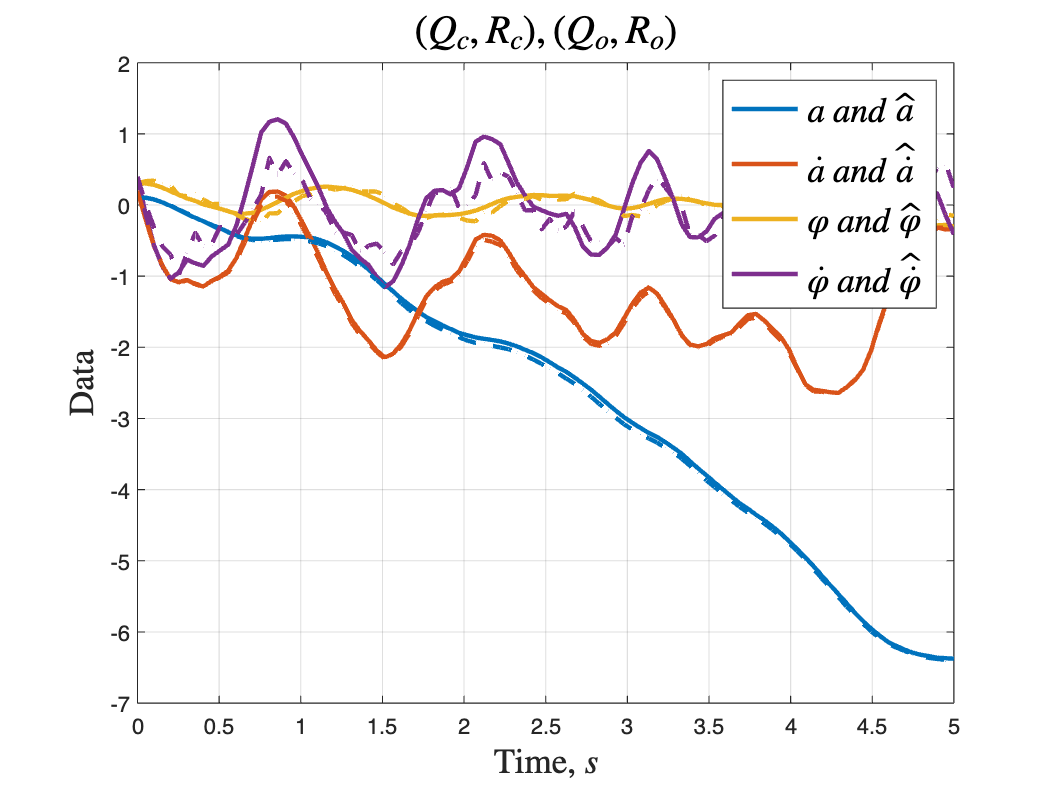


time = linspace(0, 5, 100);
x0 = [0.1; 0.2; 0.3; 0.4; 0; 0; 0; 0];


% uF = chol(Fs*F)*randn(1, SIZE+1);
% uXi = chol(Fs*XI)*randn(2, SIZE+1);
f = randn(100, 4)/10;
xi = randn(100, 2)/10;

%%
sys = ss([A+B*K -B*K; zeros(4,4) A+L*C], [eye(4) zeros(4,2); eye(4) L], zeros(1,8), zeros(1,1));
[y, t1, x1] = lsim(sys, [f xi], time, x0);

plot(t1, x1(:, 1), LineWidth=2.0, Color='#0072BD');
hold on;
plot(t1, x1(:, 2), LineWidth=2.0, Color='#D95319');
hold on;
plot(t1, x1(:, 3), LineWidth=2.0, Color='#EDB120');
hold on;
plot(t1, x1(:, 4), LineWidth=2.0, Color='#7E2F8E');
hold on;
plot(t1, x1(:, 1)-x1(:, 5), LineWidth=2.0, Color='#0072BD', LineStyle='--');
hold on;
plot(t1, x1(:, 2)-x1(:, 6), LineWidth=2.0, Color='#D95319', LineStyle='--');
hold on;
plot(t1, x1(:, 3)-x1(:, 7), LineWidth=2.0, Color='#EDB120', LineStyle='--');
hold on;
plot(t1, x1(:, 4)-x1(:, 8), LineWidth=2.0, Color='#7E2F8E', LineStyle='--');
hold on;
legend('$a\:and\:\hat{a}$', '$\dot{a}\:and\:\hat{\dot{a}}$','$\varphi\:and\:\hat{\varphi}$', '$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$(Q_c, R_c), (Q_o, R_o)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

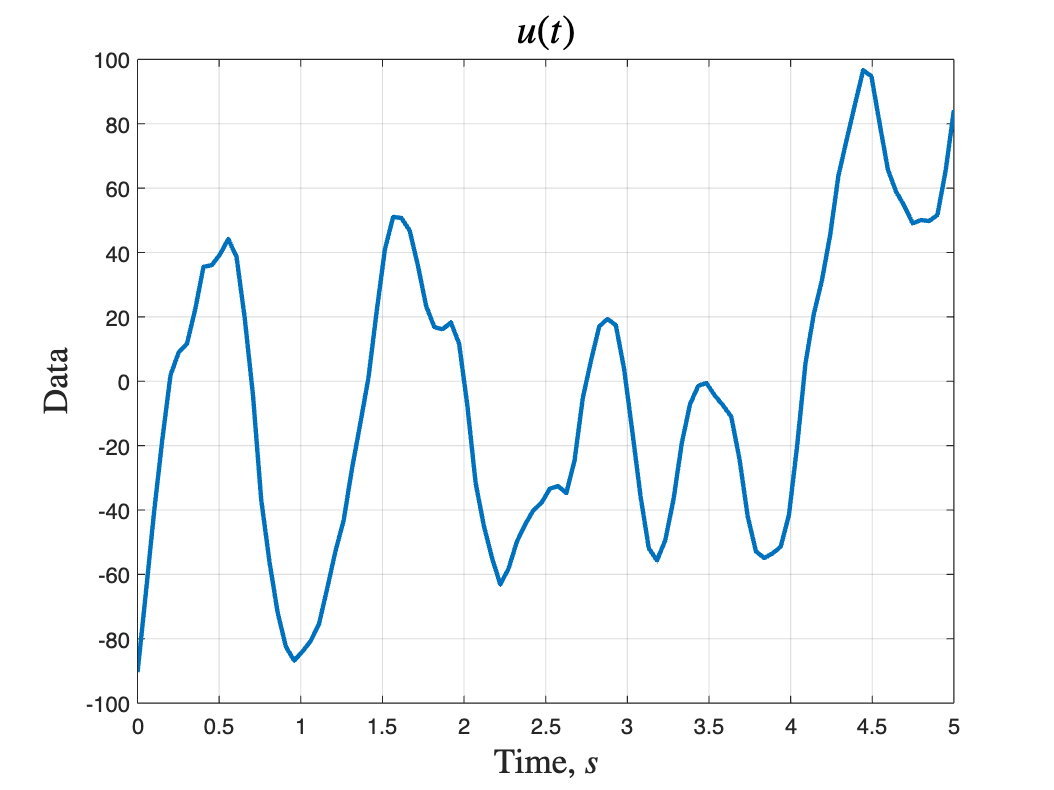


u = K*x1(:,1:4)';
plot(t1, u, LineWidth=2.0, Color='#0072BD');
title('$u(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

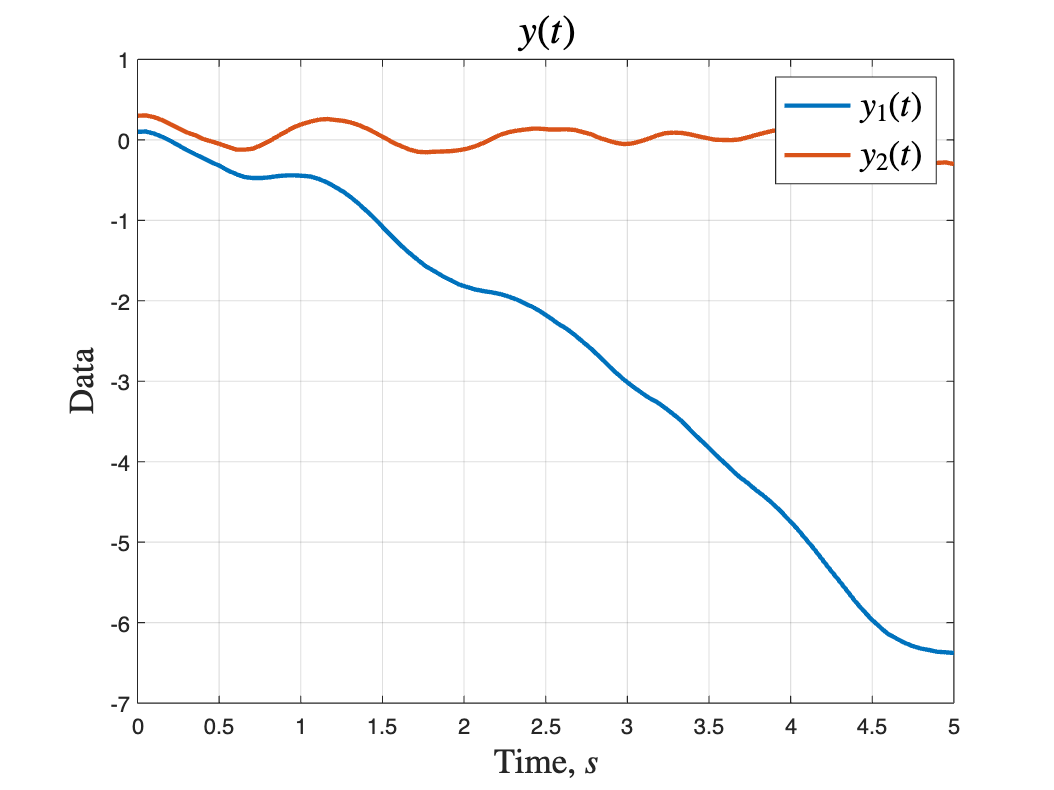


y = C*x1(:,1:4)';
plot(t1, y, LineWidth=2.0);
legend('$y_1(t)$', '$y_2(t)$', 'Interpreter', 'latex', 'FontSize', 16);
title('$y(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

## 5.5 LQG для нелинейной модели

K = -lqr(A, B, eye(4), eye(1))

K =     1.0000    5.2278 -236.8155  -51.2390


L = lqe(A, eye(4), C, eye(4), eye(2))

L =     1.7425    0.2969
    1.0623    1.8921
    0.2969    9.3332
    1.3965   43.0980


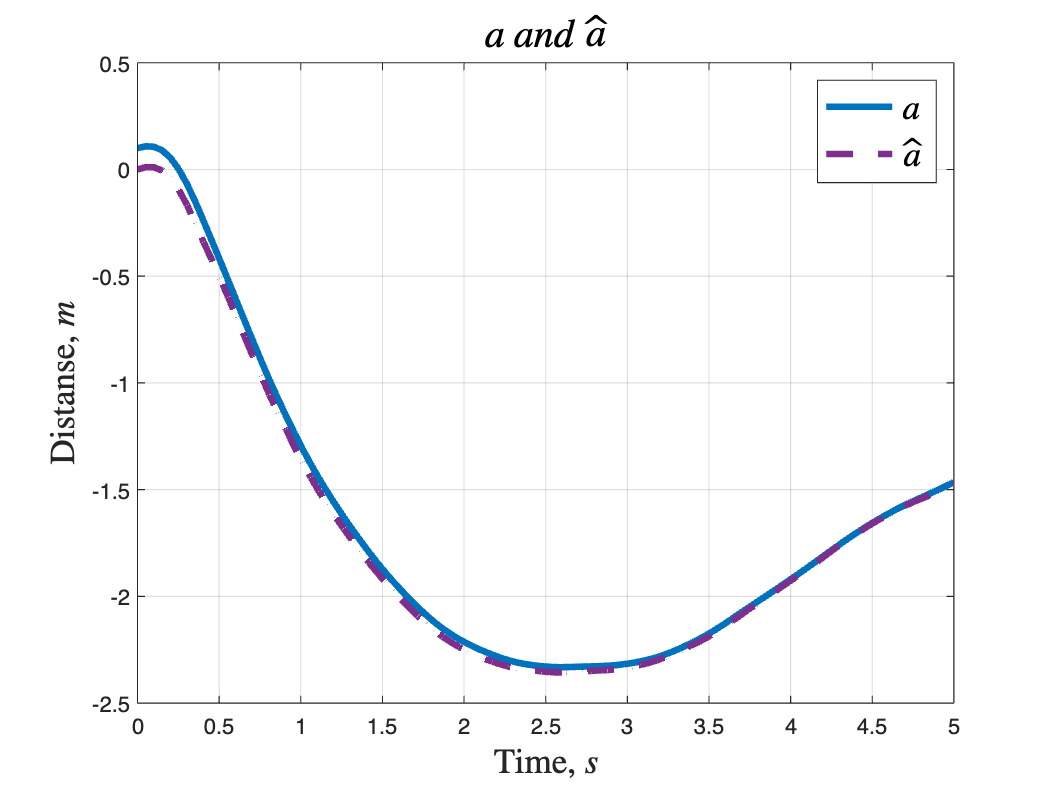


tspan = linspace(0, 5, 100);
x0 = [0.1; 0.2; 0.3; 0.4; 0; 0; 0; 0];


% uF = chol(Fs*F)*randn(1, SIZE+1);
% uXi = chol(Fs*XI)*randn(2, SIZE+1);
f = randn(1, 1)*3;
xi = randn(2, 1);

%%
[t1, x1] = ode45(@(t, x) estimator(t, x, M, m, g, l, 0, K, L, 0), tspan, x0);

plot(t1, x1(:, 1), LineWidth=3.0, Color='#0072BD');
hold on;
plot(t1, x1(:, 5), LineWidth=3.0, Color='#7E2F8E', LineStyle='--');
legend('$a$', '$\hat{a}$','Interpreter', 'latex', 'FontSize', 16);
title('$a\:and\:\hat{a}$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Distanse, $m$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

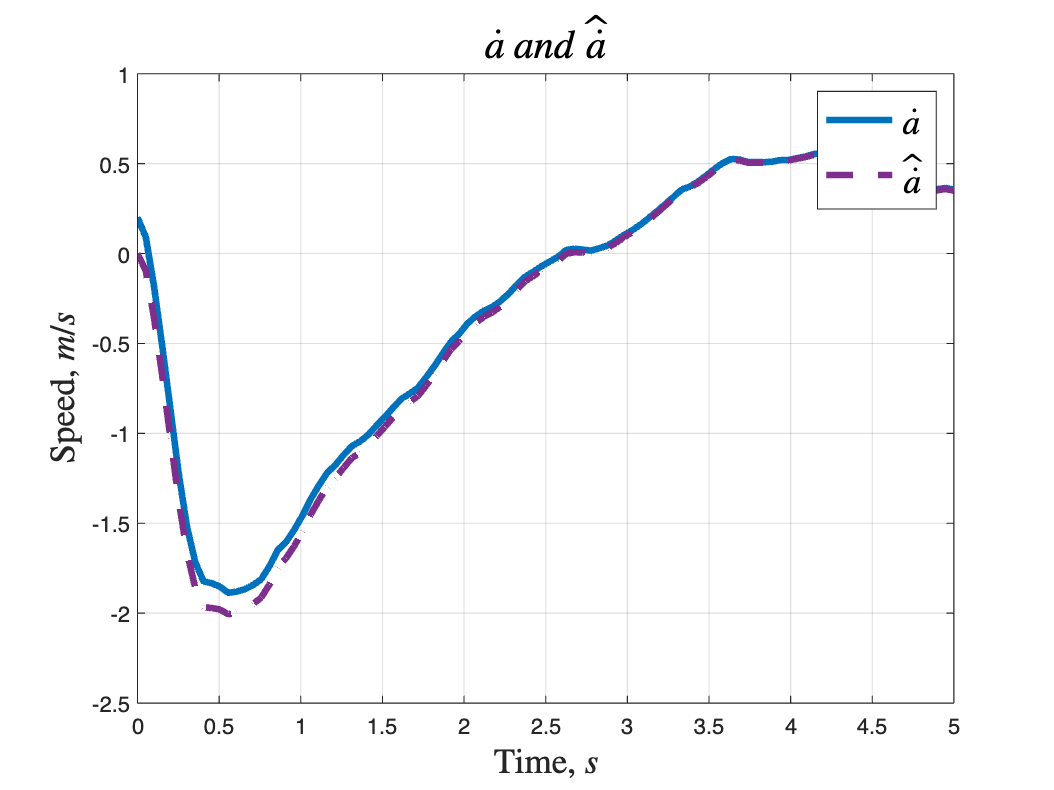



plot(t1, x1(:, 2), LineWidth=3.0, Color='#0072BD');
hold on;
plot(t1, x1(:, 6), LineWidth=3.0, Color='#7E2F8E', LineStyle='--');
legend('$\dot{a}$', '$\hat{\dot{a}}$','Interpreter', 'latex', 'FontSize', 16);
title('$\dot{a}\:and\:\hat{\dot{a}}$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Speed, $m/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

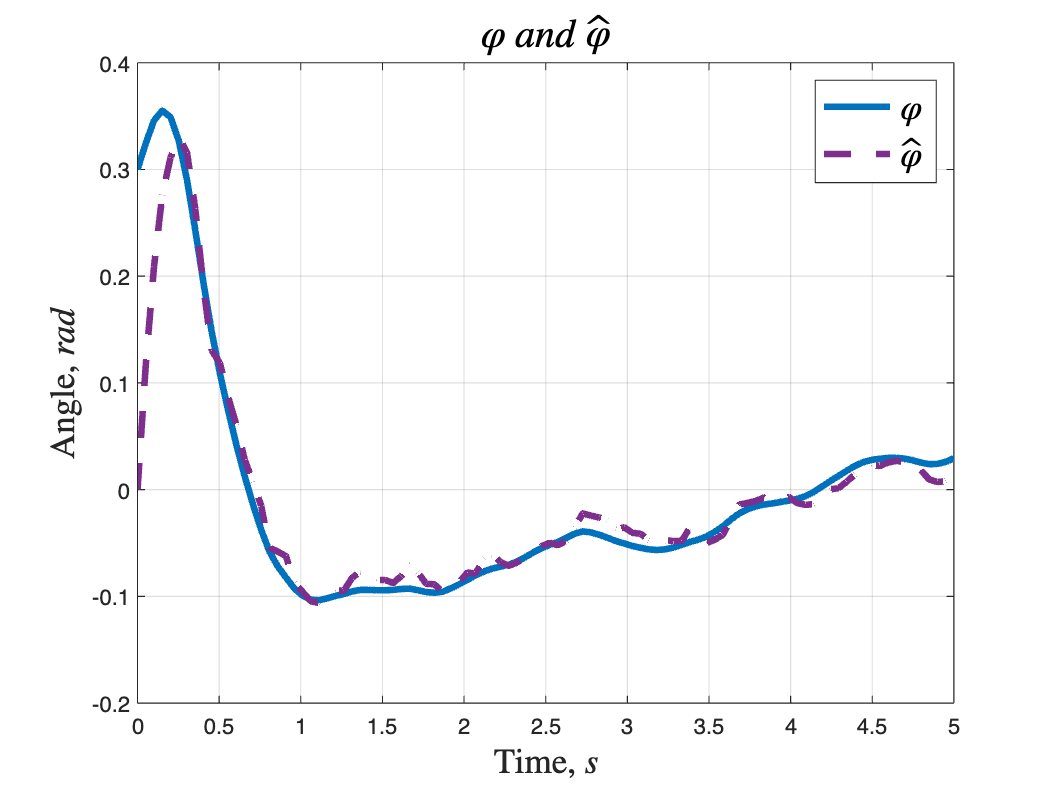


plot(t1, x1(:, 3), LineWidth=3.0, Color='#0072BD');
hold on;
plot(t1, x1(:, 7), LineWidth=3.0, Color='#7E2F8E', LineStyle='--');
legend('$\varphi$', '$\hat{\varphi}$','Interpreter', 'latex', 'FontSize', 16);
title('$\varphi\:and\:\hat{\varphi}$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

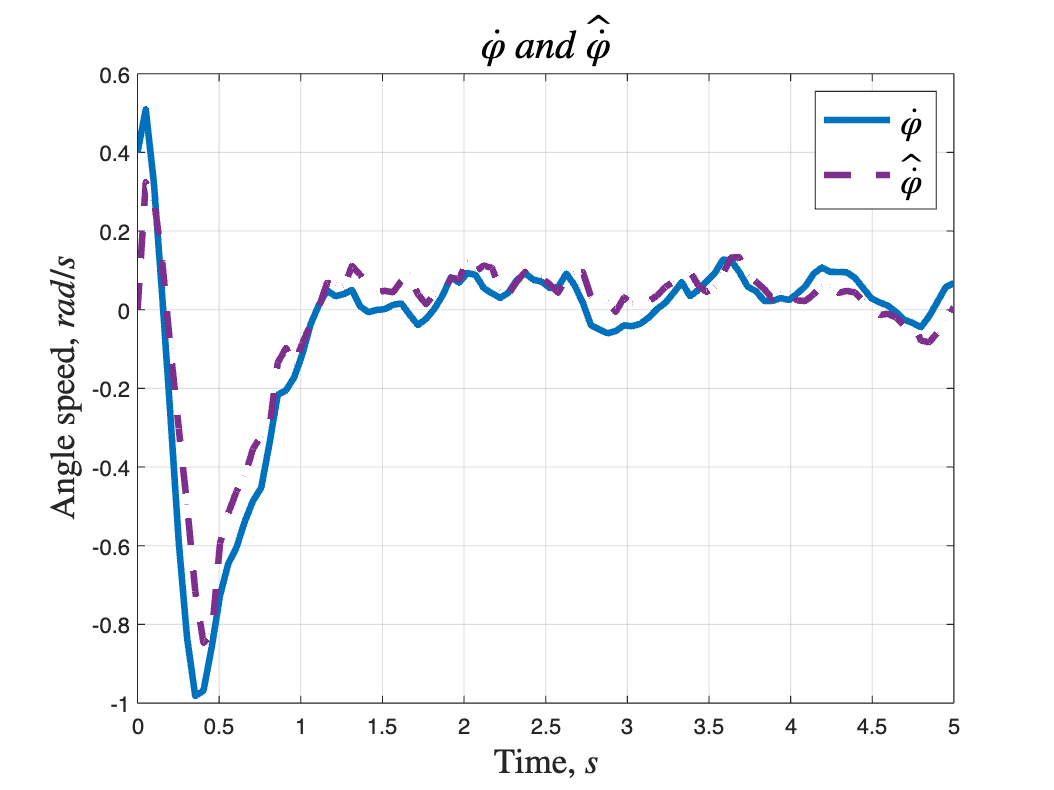


plot(t1, x1(:, 4), LineWidth=3.0, Color='#0072BD');
hold on;
plot(t1, x1(:, 8), LineWidth=3.0, Color='#7E2F8E', LineStyle='--');
legend('$\dot{\varphi}$', '$\hat{\dot{\varphi}}$','Interpreter', 'latex', 'FontSize', 16);
title('$\dot{\varphi}\:and\:\hat{\dot{\varphi}}$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle speed, $rad/s$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

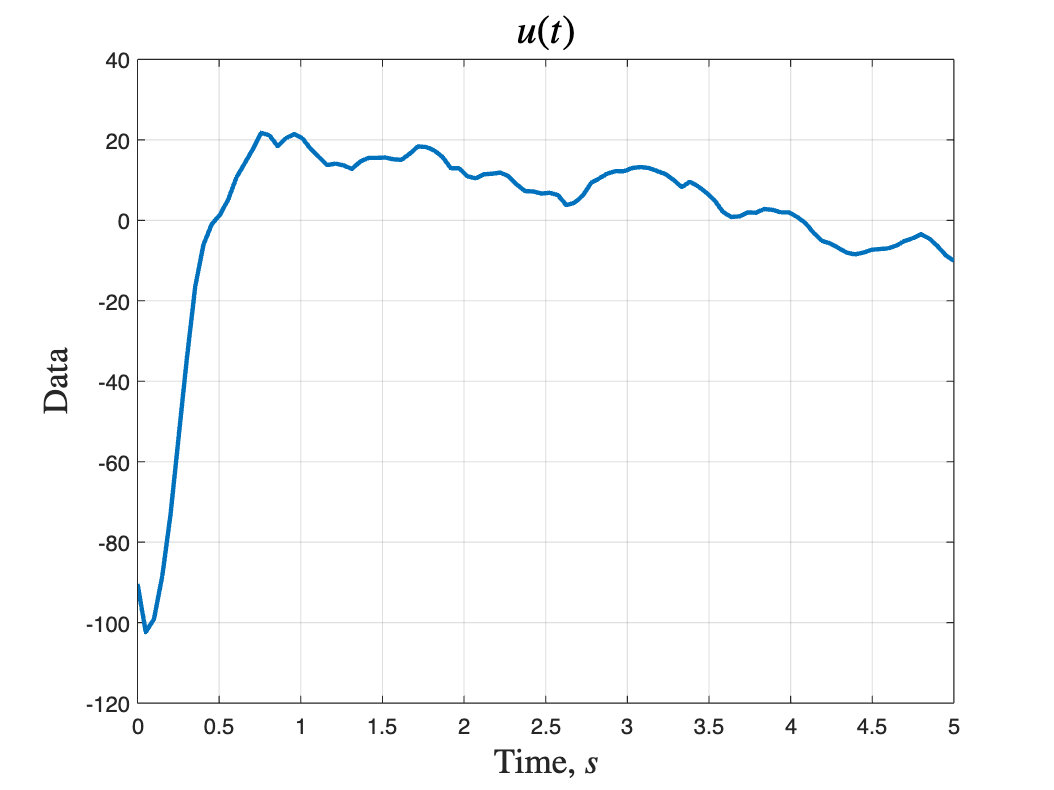


u = K*x1(:,5:8)';
plot(t1, u, LineWidth=2.0, Color='#0072BD');
title('$u(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

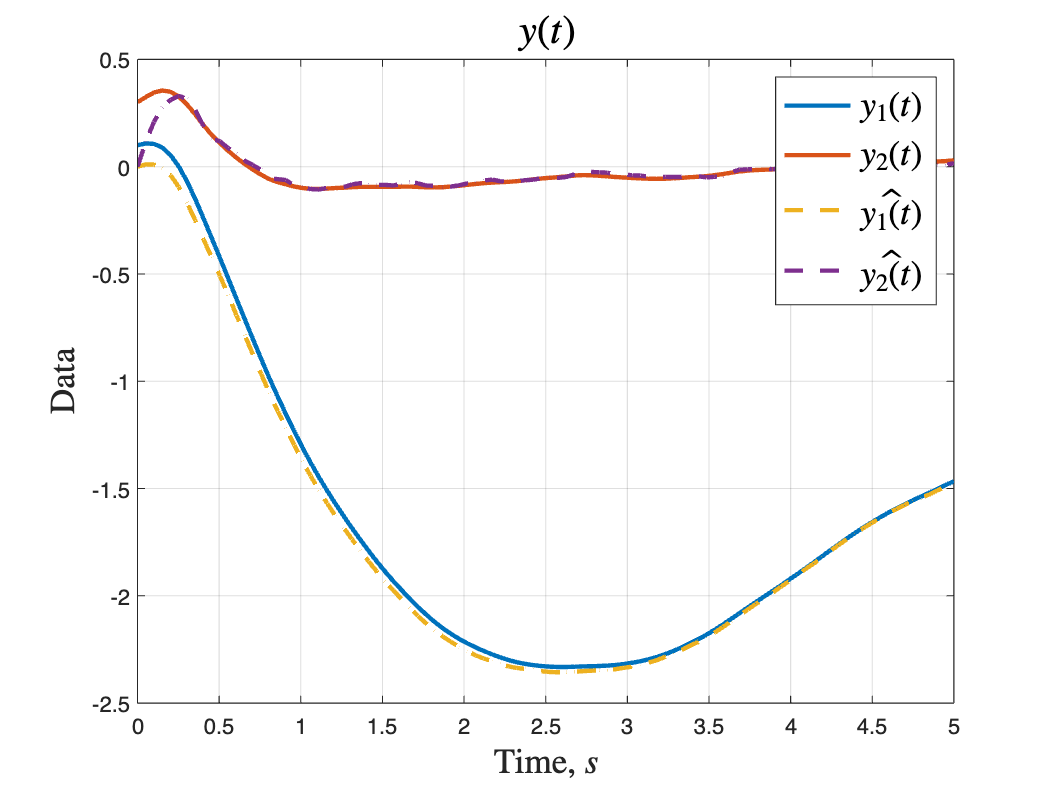


y = C*x1(:,1:4)';
yh = C*x1(:,5:8)';
plot(t1, y, LineWidth=2.0);
hold on;
plot(t1, yh, LineWidth=2.0, LineStyle='--');
legend('$y_1(t)$', '$y_2(t)$', '$\hat{y_1(t)}$', '$\hat{y_2(t)}$', 'Interpreter', 'latex', 'FontSize', 16);
title('$y(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;


s1 = reshape(x1,[size(x1, 1),8])';

xe1 = abs(s1(1:4,:))-abs(s1(5:8,:));

max(abs(xe1(1,:)))

ans = 0.1000

max(abs(xe1(2,:)))

ans = 0.2000

max(abs(xe1(3,:)))

ans = 0.3000

max(abs(xe1(4,:)))

ans = 0.4000


max(abs(x1(:,1)))

ans = 2.3319


max(abs(x1(:,3)))

ans = 0.3551


max(abs(K*(s1(5:8,:))))

ans = 75.2012

## 6.1 Решение задачи компенсации

Переобозначение параметров системы

A1 = A;
A2 = [0, 9, 0, 0, 0, 0;
    -9, 0, 0, 0, 0, 0;
    0, 0, 0, 6, 0, 0;
    0, 0, -6, 0, 0, 0;
    0, 0, 0, 0, 0, 3;
    0, 0, 0, 0, -3, 0;];
F = [0.5, 0, 1, 0, -0.8, 0];
C2 = [0, 0, 1, 0];
x0 = [0.1; 0.2; 0.3; 0.4];
B2 = D*F

B2 =          0         0         0         0         0         0
    0.1000         0    0.2000         0   -0.1600         0
         0         0         0         0         0         0
    2.2000         0    4.4000         0   -3.5200         0


Вычисление LQR

Q = eye(4);
R = 1;
K1 = -lqr(A1, B, eye(4), eye(1))

K1 =     1.0000    5.2278 -236.8155  -51.2390


Вычисление матрицы K2 регулятора

cvx_begin sdp quiet;
variables P(length(A1),length(A2)) Y(1,length(A2))
P*A2 - A1*P == B*Y + B2
C2*P == 0;
cvx_end;
K2 = Y - K1*P

K2 =   -11.0123   -0.5809  -22.0556   -1.7426   17.7778    2.7882


Линейное моделирование

t = linspace(0, 10, 10001);
sysw = ss(A2, zeros(6, 1), zeros(1, 6), 0);
[fsfv,tOut,w] = initial(sysw, [0.5, 0, 1, 0, 0.9, 0], t);

plot(tOut, F*w',LineWidth=2.0)
title('$f(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;


sys = ss(A1+B*K1, B2+B*K2, C2, zeros()); 
[z,t,x] = lsim(sys, w, t, x0);

plot(t, x, LineWidth=2.0);
title('$x_i(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;


plot(t, x(:,3), LineWidth=2.0);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;


plot(t, z, LineWidth=2.0);
title('$z(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;

Нелинейное моделирование

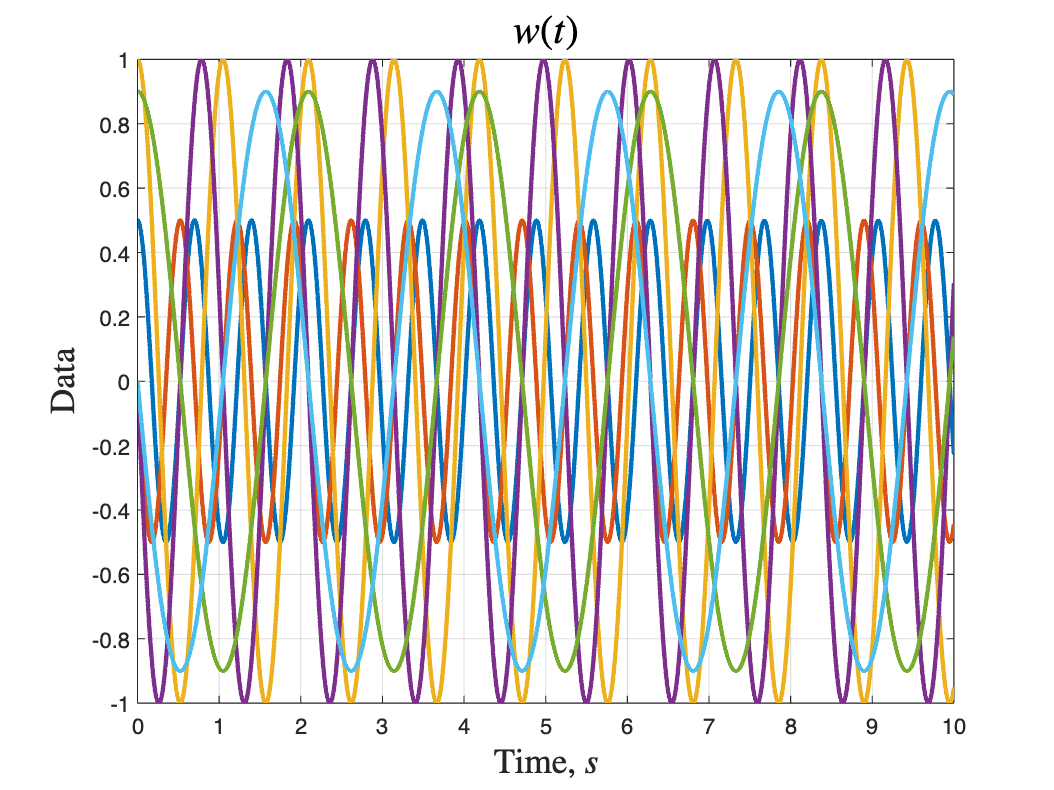

F = [0.5, 0.1, 1, 0, -0.8, 0];
t = 0:0.001:10;
x0 = [0.1; 0.2; 0.3; 0.4; 0.5; 0; 1; 0; 0.9; 0];

[t1,x1] = ode45(@(t,xw)combined(t, xw, M, m, g, l, K1, K2, A2, F, C2, 0), t, x0);

x1 = reshape(x1,[size(x1, 1),10])';
plot(t1, x1(5:10,:), LineWidth=2.0);
title('$w(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;

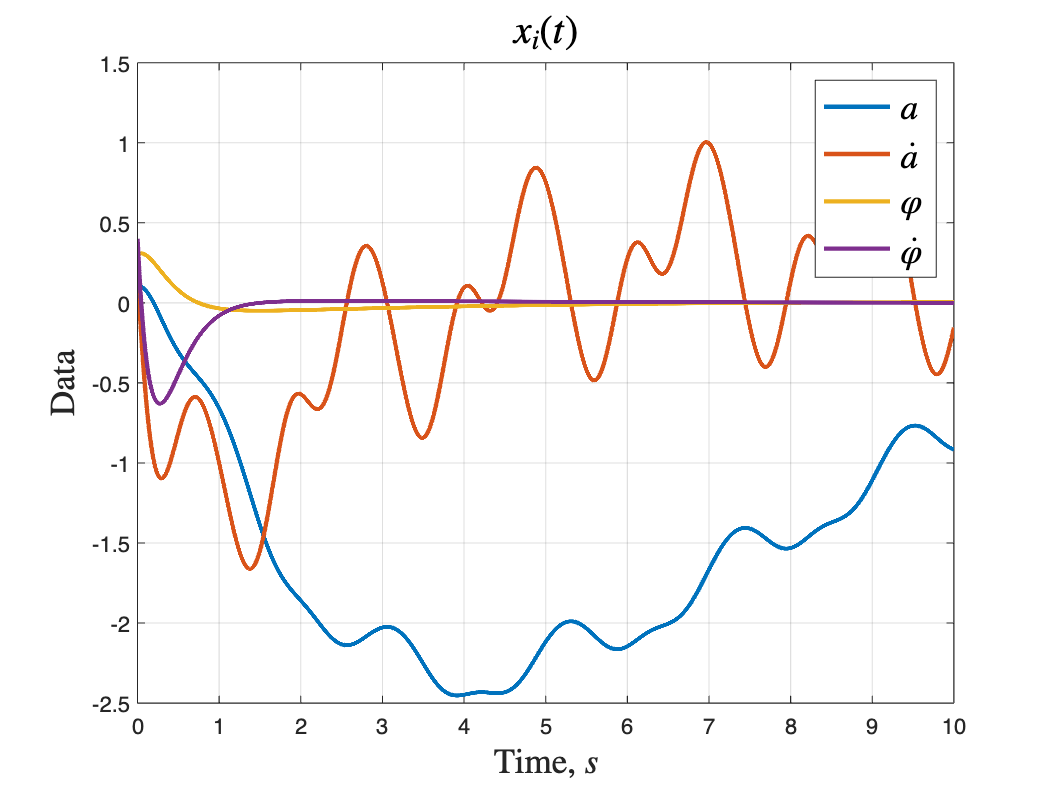


plot(t1, x1(1:4,:), LineWidth=2.0);
title('$x_i(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
legend('$a$', '$\dot{a}$','$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex', 'FontSize', 16);
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;

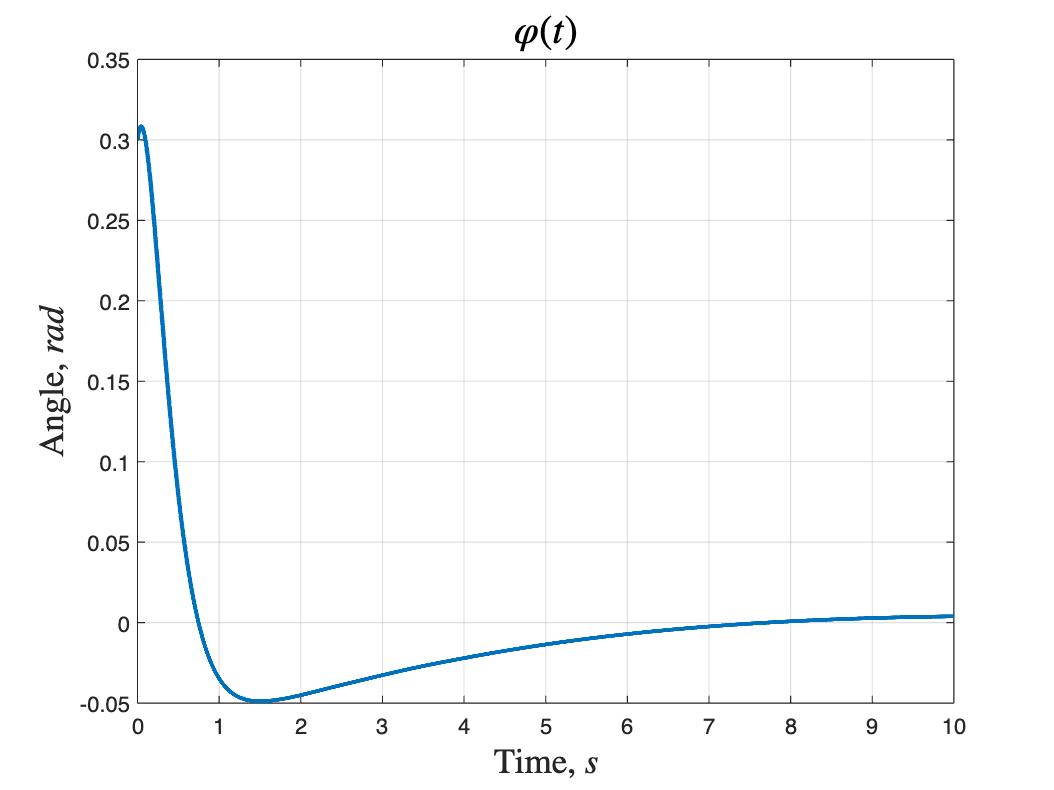



plot(t1, x1(3,:), LineWidth=2.0);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;

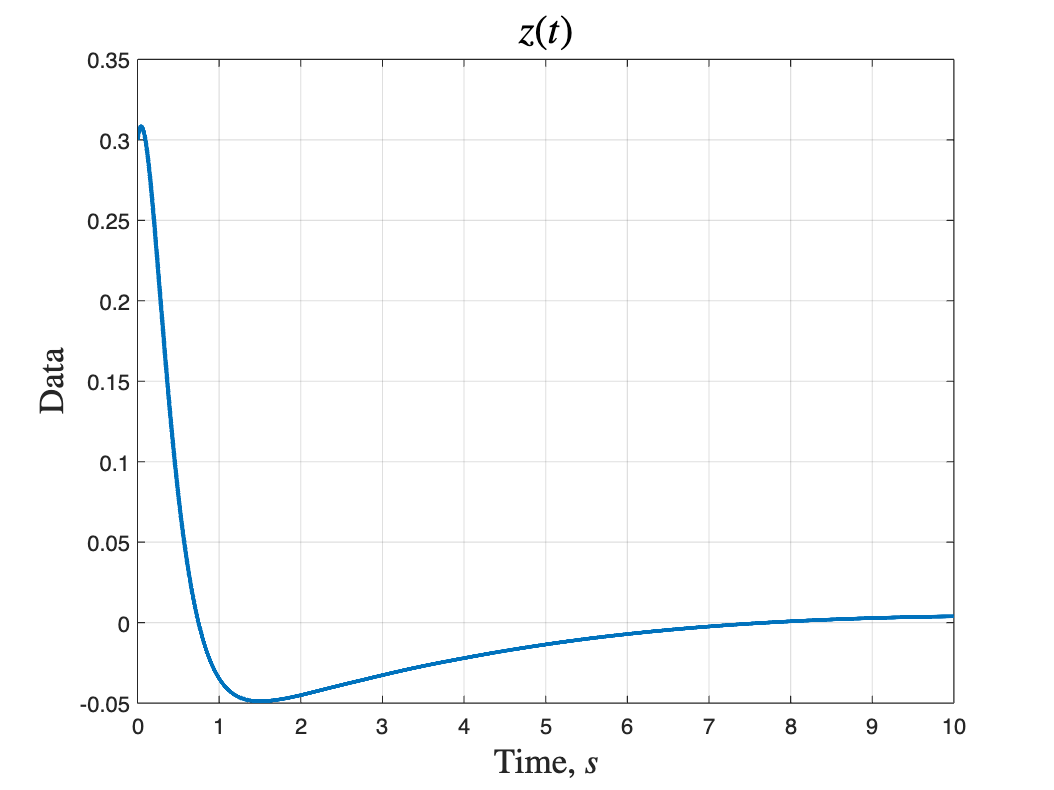


z = C2*x1(1:4,:);
plot(t1, z, LineWidth=2.0);
title('$z(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;
hold off;

Сравнение линейной и нелинейной системы

xn = x1(3,:)'

xn =     0.3000
    0.3004
    0.3008
    0.3012
    0.3015
    0.3019
    0.3022
    0.3025
    0.3029
    0.3032


xl = x(:,3)

xl =     0.3000
    0.3004
    0.3008
    0.3011
    0.3015
    0.3019
    0.3022
    0.3025
    0.3028
    0.3031


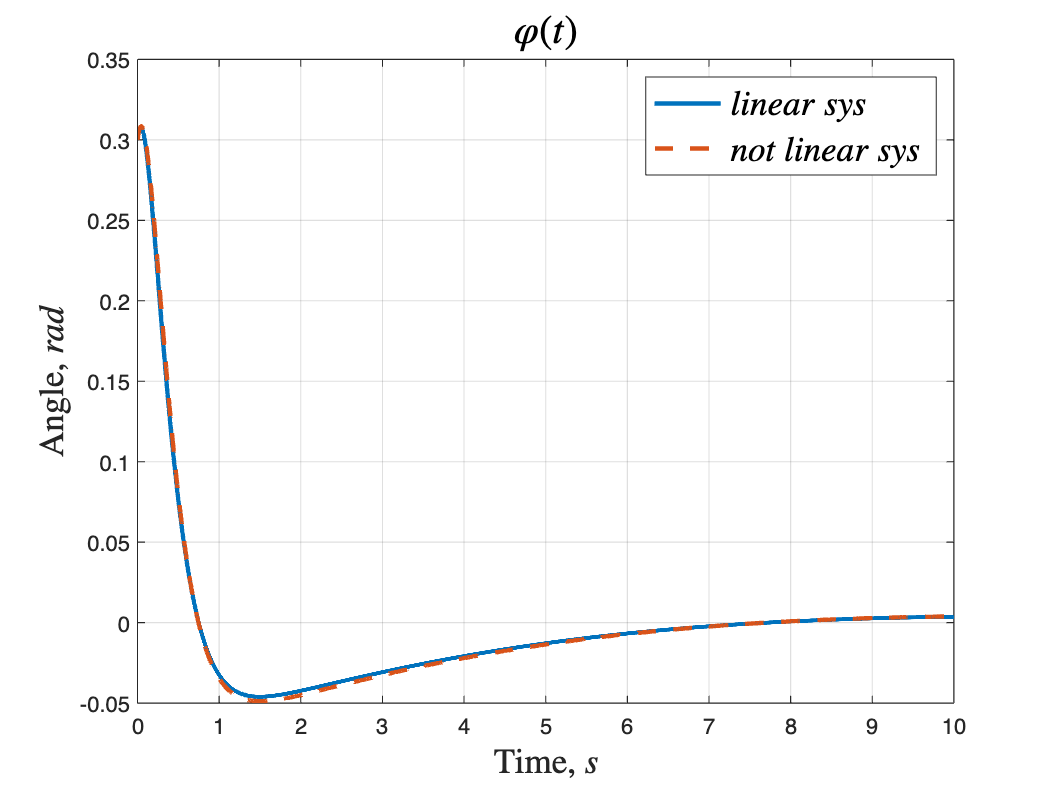

plot(t1, xl, LineWidth=2.0);
hold on;
plot(t1, xn, LineWidth=2.0,  LineStyle='--');
legend('$linear\:sys$', '$not\:linear\:sys$', 'Interpreter', 'latex', 'FontSize', 16);
title('$\varphi(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 16);
grid on;

## 6.2 Решение задачи слежения

Переобозначение параметров системы

A1 = A;
A2 = [0, 9, 0, 0, 0, 0;
    -9, 0, 0, 0, 0, 0;
    0, 0, 0, 6, 0, 0;
    0, 0, -6, 0, 0, 0;
    0, 0, 0, 0, 0, 3;
    0, 0, 0, 0, -3, 0;];
F = [0.5, 0, 1, 0, -0.8, 0];
D2 = [0.5, 0, 1, 0, -0.8, 0];
C2 = [0, 0, 1, 0];
B2 = D*[0, 0, 0, 0, 0, 0];

Вычисление LQR

Q = eye(4);
R = 1;
[P1, ~, ~] = icare(A1, B, Q, R, [], [], [], []);
K1 = -inv(R) * B' * P1

K1 =     1.0000    5.2278 -236.8155  -51.2390


Вычисление матрицы K2 регулятора

cvx_begin sdp quiet;
variables P(length(A1),length(A2)) Y(1,length(A2))
P*A2 - A1*P == B*Y;
C2*P + D2 == 0;
cvx_end;
K2 = Y - K1*P

K2 =   138.3027 -215.9669   51.7567 -283.2122   65.9413  103.0384


Моделирование линейной системы

x0 = [0.1; 0.2; 0.3; 0.4];
w0 = [0.5, 0, 1, 0, 0.9, 0];

% sysw = ss(A2, zeros(6, 1), zeros(1, 6), 0);
% [fsfv,tOut,w] = initial(sysw, [0.5, 0, 1, 0, 0.9, 0], t);
% 

plot(out.xx.Time, -1*out.xx.Data, LineWidth=2.0);
hold on;
plot(out.ww.Time, out.ww.Data, LineWidth=2.0, LineStyle="--");
title('$g(t)\:compare\:to\:\varphi(t)$','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Angle, $rad$', 'Interpreter', 'latex', 'FontSize', 15);
legend('$\varphi(t)$', '$g(t)$', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


plot(out.z.Time, out.z.Data, LineWidth=2.0);
title('$z(t)$','Interpreter', 'latex', 'FontSize', 18, 'FontWeight','bold');
xlabel('Time, $s$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 16);
grid on;

Моделирование нелинейной системы

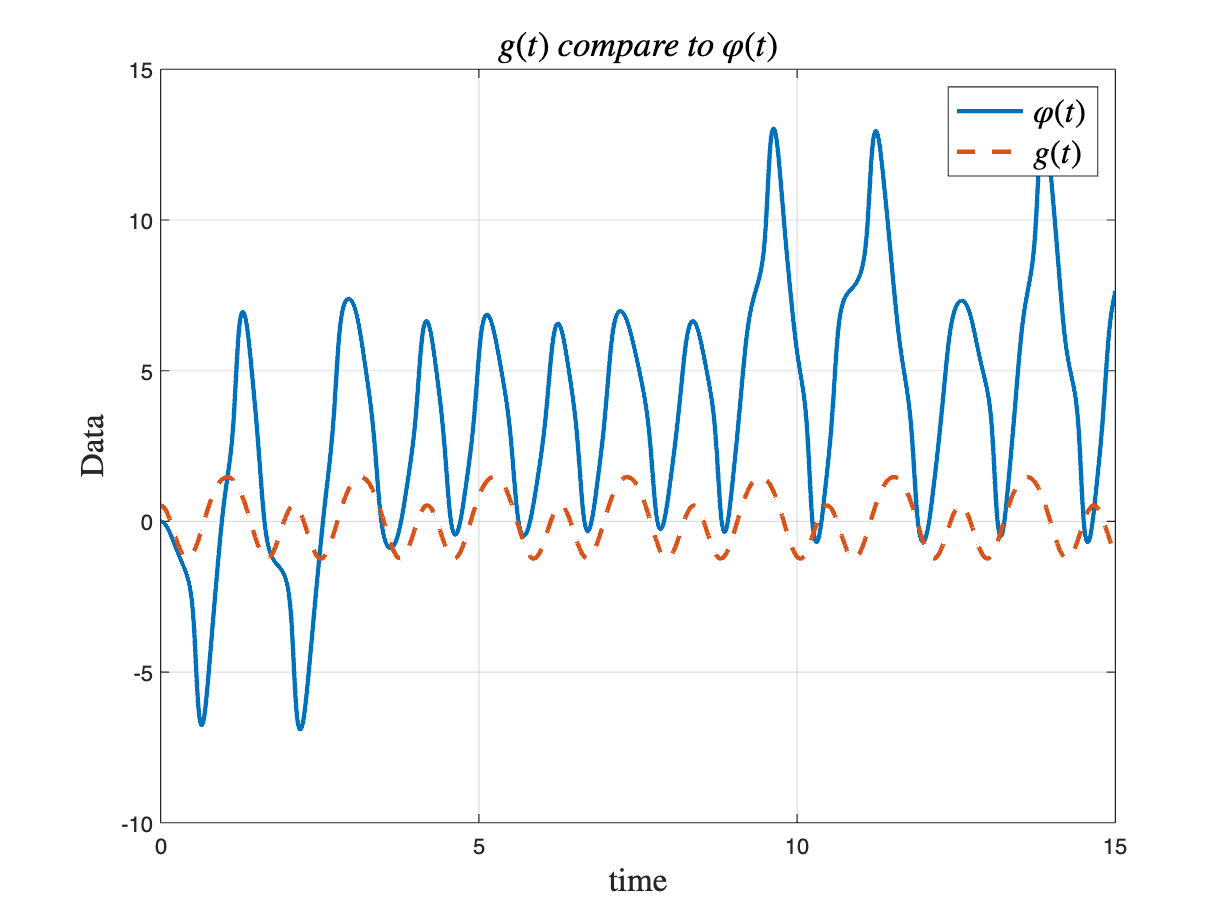

m = 1;
M = 10;
l = 0.5;
t = 0:0.001:15;
w0 = [0.5, 0, 1, 0, 0.9, 0];
x0 = [0; 0; 0; 0; w0'];

[t1,x1] = ode45(@(t,xw)combined(t, xw, M, m, g, l, K1, K2, A2, F, C2, D2), t, x0);

x1 = reshape(x1,[size(x1, 1),10])';
% x1(3,:)
gt = F*x1(5:10,:);
z = C2*x1(1:4,:) + D2*x1(5:10,:);
plot(t1, -C2*x1(1:4,:), LineWidth=2.0);
hold on;
plot(t1, gt, LineWidth=2.0, LineStyle="--");
hold on;
title('$g(t)\:compare\:to\:\varphi(t)$','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
legend('$\varphi(t)$', '$g(t)$', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

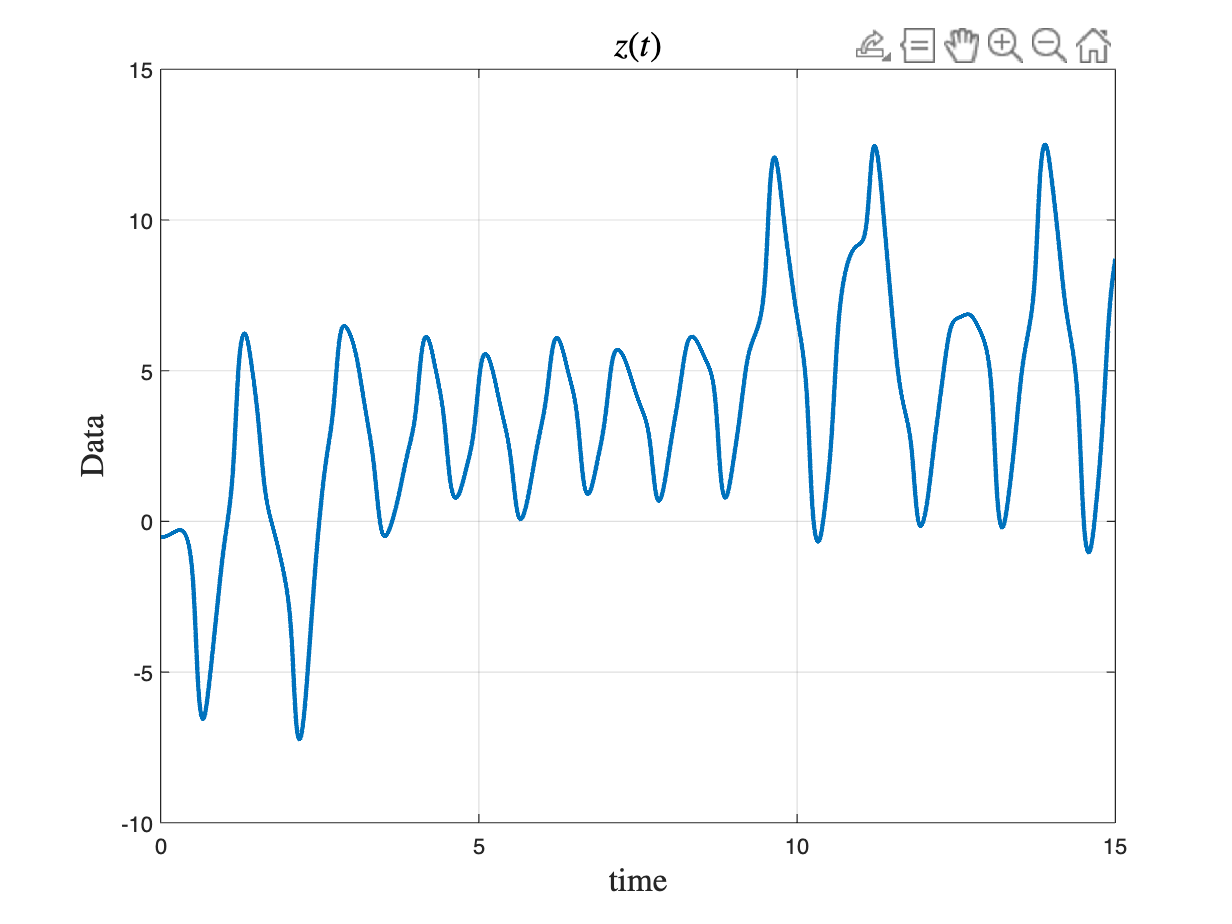


plot(t1, -z, LineWidth=2.0);
hold on;
title('$z(t)$','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

function dx = pendulum_equations(t, x, m, M, l, g, u)
    % Состояния системы
    theta = x(3);  % Угол отклонения маятника
    theta_dot = x(4);  % Угловая скорость маятника
    x_pos = x(1);  % Позиция тележки
    x_dot = x(2);  % Скорость тележки
    % Вычисление производных состояни
    ddtheta = ((M+m)/(l*(M+m*sin(theta)^2)))*((g*sin(theta)+(u*cos(theta)-(m*l*theta_dot^2*sin(theta)*cos(theta)))/(M+m)));
    ddx = (1/(M+m*sin(theta)^2))*(m*g*sin(theta)*cos(theta)-m*l*theta_dot^2*sin(theta)+u);

    % Составление вектора производных состояний
    dx = [x_dot; ddx;theta_dot; ddtheta];
end

function dxdt = observer(~, x, M, m, g, l, f, K, L)
    % State variables
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    x4 = x(4);

    % Estimated state variables
    xhat1 = x(5);
    xhat2 = x(6);
    xhat3 = x(7);
    xhat4 = x(8);

    % No control input
    u = K * [x1; x2; x3; x4];
    % u = K * [xhat1; xhat2; xhat3; xhat4];
    % Dynamics equations for the actual system
    dx1dt = x2;
    dx3dt = x4;

    sin_x3 = sin(x3);
    cos_x3 = cos(x3);
    denominator = M + m * sin_x3^2;

    dx2dt = (1 / denominator) * (m * g * sin_x3 * cos_x3 + cos_x3 / l * f + u - m * l * sin_x3 * x4^2);
    dx4dt = (1 / denominator) * ((M + m) * g / l * sin_x3 + (M + m) / (m * l^2) * f + cos_x3 / l * u - m * sin_x3 * cos_x3 * x4^2);

    % Actual system state derivatives
    dxdt_actual = [dx1dt; dx2dt; dx3dt; dx4dt];

    % Output equations
    y = [x1; x3];

    % Dynamics equations for the nonlinear estimator
    sin_xhat3 = sin(xhat3);
    cos_xhat3 = cos(xhat3);
    denominator_hat = M + m * sin_xhat3^2;

    dxhat1dt = xhat2;
    dxhat3dt = xhat4;

    dxhat2dt = (1 / denominator_hat) * (m * g * sin_xhat3 * cos_xhat3 + cos_xhat3 / l * f + u - m * l * sin_xhat3 * xhat4^2);
    dxhat4dt = (1 / denominator_hat) * ((M + m) * g / l * sin_xhat3 + (M + m) / (m * l^2) * f + cos_xhat3 / l * u - m * sin_xhat3 * cos_xhat3 * xhat4^2);

    % Estimated system state derivatives
    dxdt_hat = [dxhat1dt; dxhat2dt; dxhat3dt; dxhat4dt];

    % Estimator (Observer) equations
    yhat = [xhat1; xhat3];

    % Nonlinear estimator dynamics
    dxhatdt = dxdt_hat + L * (yhat-y);

    % Combine derivatives
    dxdt = [dxdt_actual; dxhatdt];
end

function dx = lincartpend(x,A,B,u)
dx = A*x + B*u;
end

function dx = cartpendlin(x,A,B,C,D,L,K,f,xi)

u = K*x(5:8);
dx(1:4,1) = A*x(1:4) + B*u + D*f;
y = C*x(1:4) + xi;
dx(5:8,1) = A*x(5:8) + B*u + L*(C*x(5:8) - y);
end

function dxdt = observerLQG(~, x, M, m, g, l, f, K, L, xi)
    % State variables
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    x4 = x(4);

    % Estimated state variables
    xhat1 = x(5);
    xhat2 = x(6);
    xhat3 = x(7);
    xhat4 = x(8);

    % No control input
    % u = K * [x1; x2; x3; x4];
    u = K * [xhat1; xhat2; xhat3; xhat4];
    % Dynamics equations for the actual system
    dx1dt = x2;
    dx3dt = x4;

    sin_x3 = sin(x3);
    cos_x3 = cos(x3);
    denominator = M + m * sin_x3^2;

    dx2dt = (1 / denominator) * (m * g * sin_x3 * cos_x3 + cos_x3 / l * f + u - m * l * sin_x3 * x4^2);
    dx4dt = (1 / denominator) * ((M + m) * g / l * sin_x3 + (M + m) / (m * l^2) * f + cos_x3 / l * u - m * sin_x3 * cos_x3 * x4^2);

    % Actual system state derivatives
    dxdt_actual = [dx1dt; dx2dt; dx3dt; dx4dt];

    % Output equations
    y = [x1; x3] + xi;

    % Dynamics equations for the nonlinear estimator
    sin_xhat3 = sin(xhat3);
    cos_xhat3 = cos(xhat3);
    denominator_hat = M + m * sin_xhat3^2;

    dxhat1dt = xhat2;
    dxhat3dt = xhat4;

    dxhat2dt = (1 / denominator_hat) * (m * g * sin_xhat3 * cos_xhat3 + cos_xhat3 / l * f + u - m * l * sin_xhat3 * xhat4^2);
    dxhat4dt = (1 / denominator_hat) * ((M + m) * g / l * sin_xhat3 + (M + m) / (m * l^2) * f + cos_xhat3 / l * u - m * sin_xhat3 * cos_xhat3 * xhat4^2);

    % Estimated system state derivatives
    dxdt_hat = [dxhat1dt; dxhat2dt; dxhat3dt; dxhat4dt];

    % Estimator (Observer) equations
    yhat = [xhat1; xhat3];

    % Nonlinear estimator dynamics
    dxhatdt = dxdt_hat + L * (yhat-y);

    % Combine derivatives
    dxdt = [dxdt_actual; dxhatdt];
end

function dxwdt = combined(~, xw, M, m, g, l, K1, K2, A2, B2, C2, D)
    % Separate the state variables
    x = xw(1:4);
    w = xw(5:10);

    % State variables for the main system
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    x4 = x(4);

    % State feedback controller
    u = K1 * x + K2 * w;

    % Dynamics equations for the main system
    dx1dt = x2;
    dx3dt = x4;

    sin_x3 = sin(x3);
    cos_x3 = cos(x3);
    denominator = M + m * sin_x3^2;

    dx2dt = (1 / denominator) * (m * g * sin_x3 * cos_x3 +  u - m * l * sin_x3 * x4^2);
    dx4dt = (1 / denominator) * ((M + m) * g / l * sin_x3 + cos_x3 / l * u - m * sin_x3 * cos_x3 * x4^2);

    % dx2dt = (1 / denominator) * (m * g * sin_x3 * cos_x3 + cos_x3 / l * (B2*w) + u - m * l * sin_x3 * x4^2);
    % dx4dt = (1 / denominator) * ((M + m) * g / l * sin_x3 + (M + m) / (m * l^2) * (B2*w) + cos_x3 / l * u - m * sin_x3 * cos_x3 * x4^2);


    % Dynamics equations for the secondary system
    dwdt = A2 * w;

    % Combine the derivatives
    dxwdt = [dx1dt; dx2dt; dx3dt; dx4dt; dwdt];
end

function dxdt = estimator(~, x, M, m, g, l, f, K, L, xi)
    f = randn(1, 1)*5;
    xi = randn(2, 1)*2;    
% State variables
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    x4 = x(4);

    % Estimated state variables
    xhat1 = x(5);
    xhat2 = x(6);
    xhat3 = x(7);
    xhat4 = x(8);

    % No control input
    u = K * [xhat1; xhat2; xhat3; xhat4];

    % Dynamics equations for the actual system
    dx1dt = x2;
    dx3dt = x4;

    sin_x3 = sin(x3);
    cos_x3 = cos(x3);
    denominator = M + m * sin_x3^2;

    dx2dt = (1 / denominator) * (m * g * sin_x3 * cos_x3 + cos_x3 / l * f + u - m * l * sin_x3 * x4^2);
    dx4dt = (1 / denominator) * ((M + m) * g / l * sin_x3 + (M + m) / (m * l^2) * f + cos_x3 / l * u - m * sin_x3 * cos_x3 * x4^2);

    % Actual system state derivatives
    dxdt_actual = [dx1dt; dx2dt; dx3dt; dx4dt];

    % Output equations
    y = [x1; x3] + xi;

    % Dynamics equations for the nonlinear estimator
    sin_xhat3 = sin(xhat3);
    cos_xhat3 = cos(xhat3);
    denominator_hat = M + m * sin_xhat3^2;

    dxhat1dt = xhat2;
    dxhat3dt = xhat4;

    dxhat2dt = (1 / denominator_hat) * (m * g * sin_xhat3 * cos_xhat3 + cos_xhat3 / l * f + u - m * l * sin_xhat3 * xhat4^2);
    dxhat4dt = (1 / denominator_hat) * ((M + m) * g / l * sin_xhat3 + (M + m) / (m * l^2) * f + cos_xhat3 / l * u - m * sin_xhat3 * cos_xhat3 * xhat4^2);

    % Estimated system state derivatives
    dxdt_hat = [dxhat1dt; dxhat2dt; dxhat3dt; dxhat4dt];

    % Estimator (Observer) equations
    yhat = [xhat1; xhat3];

    % Nonlinear estimator dynamics
    dxhatdt = dxdt_hat + L * (y - yhat);

    % Combine derivatives
    dxdt = [dxdt_actual; dxhatdt];
end
